# Homework 4

## Problem 13.9: Determine the mean, ACVS and stationarity of a random process

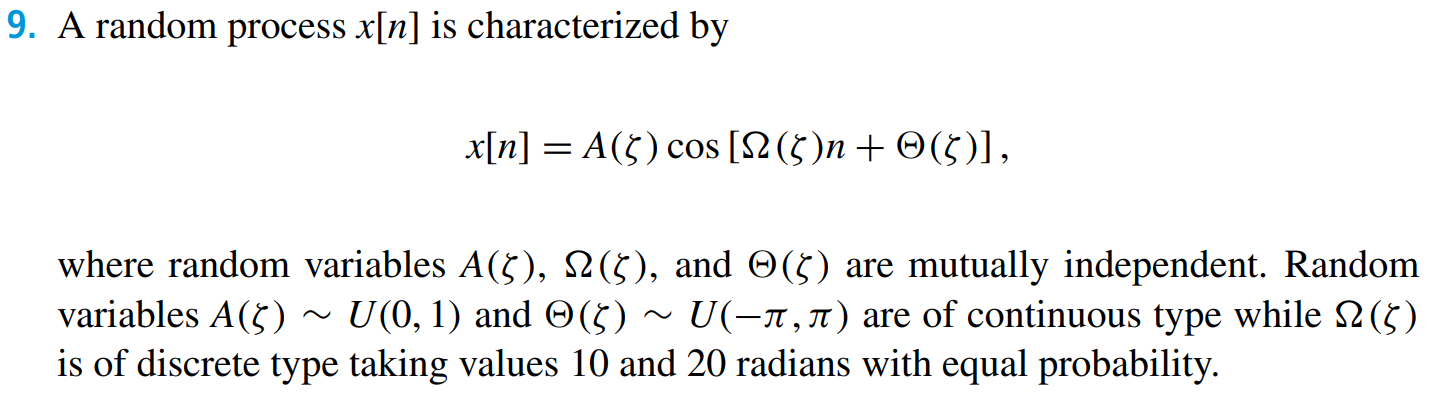

### [✔] a) Determine the mean sequence $m_x \left\lbrack n\right\rbrack$

We need to compute:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$$


Since the three random variables are independent then we can write:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\right\rbrack E\left\lbrack \;\cos \left(\Omega n+\Theta \right)\right\rbrack$$


We know that $E\left\lbrack A\right\rbrack =\frac{1}{2}$ since $A\sim U\left(0,1\right)$.

Computing the expression $E\left\lbrack \mathrm{sin}\left(\Theta \right)\right\rbrack$ requires a bit of an explanation. 

Suppose we want to compute $E\left\lbrack \mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$ where $\Theta \sim U\left(-\pi ,\pi \right)$. Let us pick one frequency $\omega$ (realise one value of $\Omega$). Then let us pick a lot of realisations of $\Theta$. Now if we plot the function $\mathrm{cos}\left(\omega \;n+\theta \right)$ for different values of $\theta$ then we will see something like this:

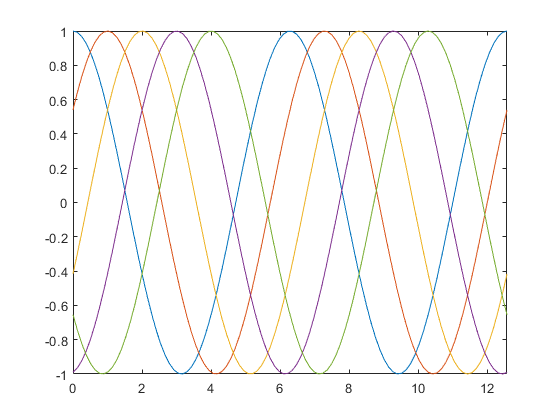

n = linspace(0, 4*pi);
plot(n, cos(n), n, cos(n-1), n, cos(n-2), n, cos(n-3), n, cos(n-4));
xlim([0, 4*pi]);

If we plot hundreds of cosine functions shifted slightly, we get a large blob of points from -1 to 1. For this reason, the quality $E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack$ will be zero because the mean value is 0. Formally, we can write:


$$E\left\lbrack \mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack =\int_{-\pi }^{\pi } f_{\Theta } \left(\Theta \right)\cdot \mathrm{cos}\left(\Omega n+\Theta \right)\;d\Theta =\frac{1}{2\pi }\int_{-\pi }^{\pi } \mathrm{cos}\left(\Omega n+\Theta \right)\;d\Theta$$


So we are integrating cosine function over $2\pi$ which is zero.

In signal processing, we like to add random shifts ala $\Theta \sim U\left(0,2\pi \right)$ to avoid that the expected value or the mean value becomes dependent on time. 

Alternatively, we can use

Using the rule $\mathrm{cos}\left(\alpha +\beta \right)=\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\beta \right)-\mathrm{sin}\left(\alpha \right)\mathrm{sin}\left(\beta \right)$, we rewrite the expression to:


$$\begin{array}{l}
E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\left(\;\cos \left(\Omega n\right)\;\cos \left(\Theta \right)-\sin \left(\Omega n\right)\sin \left(\Theta \right)\right)\right\rbrack \\
E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\cos \left(\Omega n\right)\;\cos \left(\Theta \right)-A\;\sin \left(\Omega n\right)\sin \left(\Theta \right)\right\rbrack 
\end{array}$$


At this point, we need to employ some expection rules to decompose the expression.

Let $X$ and $Y$ be two random variables and $a$ and $b$ be two constants. Following expectation identities apply:

- $E\left\lbrack a\right\rbrack =a$               e.g. $E\left(42\right)=42$

- $E\left\lbrack a\;X\right\rbrack =a\;E\left\lbrack X\right\rbrack$   e.g. if you multiply every value by 2, the expectation doubles

- $E\left\lbrack a\pm X\right\rbrack =a\pm E\left\lbrack X\right\rbrack$ e.g. if you add 42 to every case, the expectation increases by 42

- 
$$E\left\lbrack X+Y\right\rbrack =E\left\lbrack X\right\rbrack +E\left\lbrack Y\right\rbrack$$


- If $X$ and $Y$ are independent, then $E\left\lbrack \mathrm{XY}\right\rbrack =E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack$

- 
$$E\left\lbrack a\pm \mathrm{bX}\right\rbrack =a\pm E\left\lbrack b\;X\right\rbrack =a\pm b\;E\left\lbrack X\right\rbrack$$


- 
$$E\left\lbrack b\left(a\pm \textrm{X}\right)\right\rbrack =b\;E\left\lbrack a\pm \textrm{X}\right\rbrack =b\left(a\pm E\left\lbrack X\right\rbrack \right)$$


Use rule 4:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\cos \left(\Omega n\right)\;\cos \left(\Theta \right)\right\rbrack -E\left\lbrack A\;\sin \left(\Omega n\right)\sin \left(\Theta \right)\right\rbrack$$


Use rule 5 multiple times:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\right\rbrack E\left\lbrack \mathrm{cos}\left(\Omega n\right)\right\rbrack E\left\lbrack \mathrm{cos}\left(\Theta \right)\right\rbrack -E\left\lbrack A\right\rbrack E\left\lbrack \mathrm{sin}\left(\Omega n\right)\right\rbrack E\left\lbrack \mathrm{sin}\left(\Theta \right)\right\rbrack$$


**But how can we continue from here?**

We know that $\Theta \sim U\left(-\pi ,\pi \right)$ so $E\left\lbrack \Theta \right\rbrack =\frac{\pi +\left(-\pi \right)}{2}=\frac{0}{2}=0$

### b) Determine the ACVS $c_X \left\lbrack m,n\right\rbrack$

### c) Comment on the stationarity of the random process

## [✔] Problem 13.13: MSE objective function

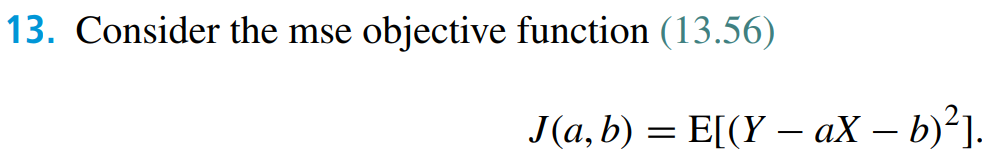

### a) Express the objective function in terms of its parameters

Use MATLAB to expand the expression inside the expected value:

syms a b X Y
expand((Y-a*X - b)^2)

$$ans = X^{2}\,a^{2}-2\,X\,Y\,a+2\,X\,a\,b+Y^{2}-2\,Y\,b+b^{2}$$

So we have:


$$J\left(a,b\right)=E\left\lbrack X^2 a^2 -2\;X\;Y\;a+2\;X\;a\;b+Y^2 -2\;Y\;b+b^2 \right\rbrack$$


Let $X$ and $Y$ be two random variables and $a$ and $b$ be two constants. Following expectation identities apply:

- $E\left\lbrack a\right\rbrack =a$               e.g. $E\left(42\right)=42$

- $E\left\lbrack a\;X\right\rbrack =a\;E\left\lbrack X\right\rbrack$   e.g. if you multiply every value by 2, the expectation doubles

- $E\left\lbrack a\pm X\right\rbrack =a\pm E\left\lbrack X\right\rbrack$ e.g. if you add 42 to every case, the expectation increases by 42

- 
$$E\left\lbrack X+Y\right\rbrack =E\left\lbrack X\right\rbrack +E\left\lbrack Y\right\rbrack$$


- If $X$ and $Y$ are independent, then $E\left\lbrack \mathrm{XY}\right\rbrack =E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack$

Use rule 4:


$$\begin{array}{l}
J\left(a,b\right)=E\left\lbrack X^2 a^2 -2\;X\;Y\;a+2\;X\;a\;b+Y^2 -2\;Y\;b+b^2 \right\rbrack \\
J\left(a,b\right)=E\left\lbrack X^2 a^2 \right\rbrack -E\left\lbrack 2\;X\;Y\;a\right\rbrack +E\left\lbrack 2\;X\;a\;b\right\rbrack +E\left\lbrack Y^2 \right\rbrack -E\left\lbrack 2\;Y\;b\right\rbrack +E\left\lbrack b^2 \right\rbrack 
\end{array}$$


Use rule 1 and rule 2:


$$J\left(a,b\right)=a^2 E\left\lbrack X^2 \right\rbrack -2\;a\;E\left\lbrack \;X\;Y\right\rbrack +2\;a\;b\;E\left\lbrack X\right\rbrack +E\left\lbrack Y^2 \right\rbrack -2\;b\;E\left\lbrack Y\right\rbrack +b^2$$


### b) Using partial derivatives to determine the values of parameters

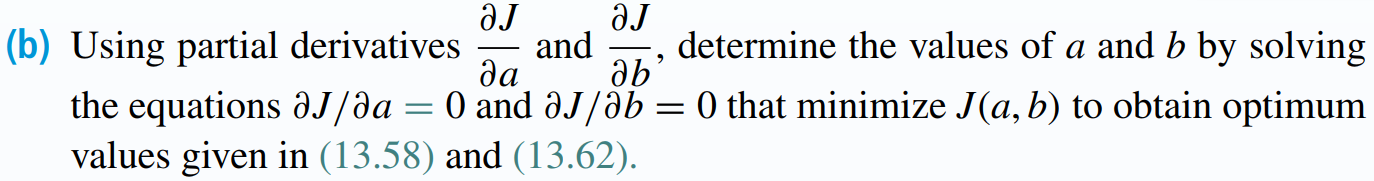

First, take the partial derivatives:


$$\frac{\partial \;J\left(a,b\right)}{\partial \;a}=2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;b\;E\left\lbrack X\right\rbrack$$
 


$$\frac{\partial \;J\left(a,b\right)}{\partial \;b}=2\;a\;E\left\lbrack X\right\rbrack -2\;E\left\lbrack Y\right\rbrack +2b$$


Next, solve the equations:

(Eq. 1) $2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;b\;E\left\lbrack X\right\rbrack =0$

(Eq. 2) $2\;a\;E\left\lbrack X\right\rbrack -2\;E\left\lbrack Y\right\rbrack +2b=0$

Isolate $b$ in (Eq. 2):


$$\begin{array}{l}
2b=-2\;a\;E\left\lbrack X\right\rbrack +2\;E\left\lbrack Y\right\rbrack \\
b=-a\;E\left\lbrack X\right\rbrack +E\left\lbrack Y\right\rbrack \\
b=E\left\lbrack Y\right\rbrack -a\;E\left\lbrack X\right\rbrack 
\end{array}$$


This corresponds to (13.58) in the book:

Now, plug the expression for $b$ into Eq. 1 in order to find an expression for $a$:


$$\begin{array}{l}
2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;b\;E\left\lbrack X\right\rbrack =0\\
2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;\left(E\left\lbrack Y\right\rbrack -a\;E\left\lbrack X\right\rbrack \right)\;E\left\lbrack X\right\rbrack =0\\
2a\;E\left\lbrack X^2 \right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;-2\;a\;E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack =0\\
2a\;E\left\lbrack X^2 \right\rbrack -2\;a\;E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack -2\;E\left\lbrack X\;Y\right\rbrack +2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;=0\\
2a\left(\;E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack \right)-2\;E\left\lbrack X\;Y\right\rbrack +2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;=0\\
2a\left(\;E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack \right)=2\;E\left\lbrack X\;Y\right\rbrack -2\;E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;\\
a\left(\;E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack \right)=E\left\lbrack X\;Y\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack \;\\
a=\frac{\;E\left\lbrack X\;Y\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack }{E\left\lbrack X^2 \right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack X\right\rbrack }=\frac{\;E\left\lbrack X\;Y\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack }{E\left\lbrack X^2 \right\rbrack -{E\left\lbrack X\right\rbrack }^2 }
\end{array}$$


We have found an expression for $a$. The numerator looks like it is the covariance:

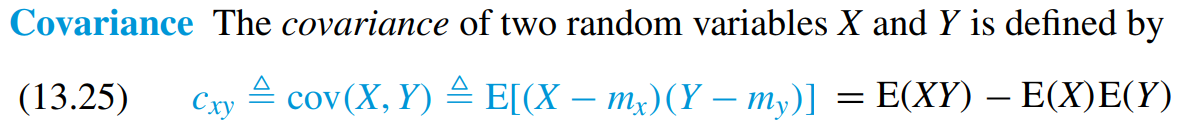

The denominator looks like it is the variance:

(13.11)     $\textrm{var}\left(X\right)=E\left\lbrack X^2 \right\rbrack -{E\left\lbrack X\right\rbrack }^2 =E\left\lbrack X^2 \right\rbrack -m_x^2$

Therefore, the derived expression is the same as (13.62) in the book.

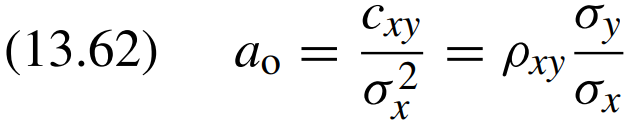

## Problem 13.22: Computing distributions

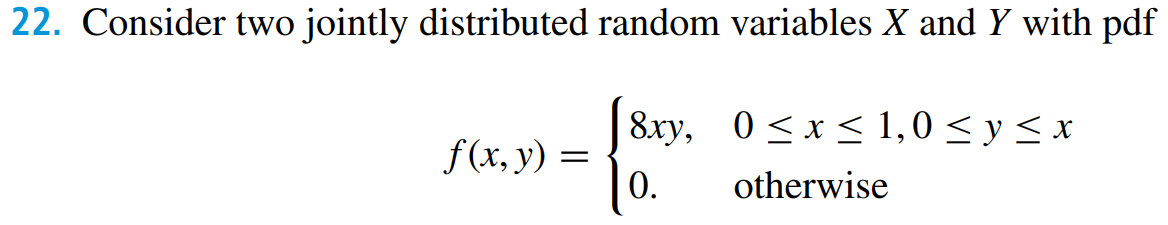

### a) Determine marginal distributions and conditional probabilities

The **marginal** distributions of random variables $X$ and $X$ are obtained by integration as follows:  

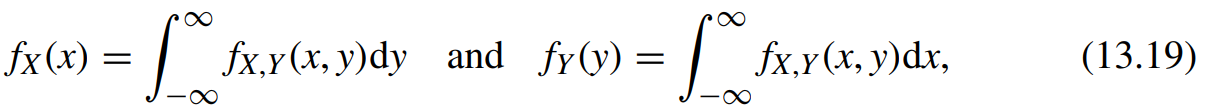

Compute the marginal distribution of $X$:


$$f\left(x\right)=\int_{-\infty }^{\infty } f\left(x,y\right)\;\mathrm{dy}=\int_0^x 8xy\;\mathrm{dy}={\left\lbrack \frac{1}{2}8xy^2 \right\rbrack }_0^x =\frac{1}{2}8xx^2 -0=4x^3 \;\mathrm{where}\;0\le x\le 1$$
 

Compute the marginal distribution of $Y$:


$$f\left(y\right)=\int_{-\infty }^{\infty } f\left(x,y\right)\;\textrm{dx}=\int_y^1 8xy\;\textrm{dx}={\left\lbrack 4yx^2 \right\rbrack }_y^1 =4y-4y^3 \;\mathrm{where}\;0\le y\le 1$$


To compute $f\left(x|y\right)$ we use following relation:

From Eq. 13.23, we know that:


$$f\left(x|y\right)=\frac{f\left(x,y\right)}{f\left(y\right)}=\frac{8\mathrm{xy}}{4y-4y^3 }=\frac{4y\cdot 2x}{4y\left(1-y^2 \right)}=\frac{2x}{1-y^2 }$$


and 


$$f\left(y|x\right)=\frac{f\left(x,y\right)}{f\left(x\right)}=\frac{8x\;y}{4x^3 }=\frac{4x\cdot 2y}{4x\cdot x^2 }=\frac{2y}{x^2 }$$


### b) Are X and Y independent?

Random variables $X$ and $Y$ are statistically independent, if $f\left(y|x\right)=f\left(y\right)$ or $f\left(x|y\right)=f\left(x\right)$.

In a) we have computed the following expressions:

- 
$$f\left(x\right)=4x^3$$


- 
$$f\left(y\right)=4y-4y^3 \;$$


- 
$$f\left(y\left|x\right.\right)=\frac{2y}{x^2 }$$


- 
$$f\left(x\left|y\right.\right)=\frac{2x}{1-y^2 }$$


Clearly$f\left(y|x\right)\not= f\left(y\right)\;\mathrm{and}\;f\left(x|y\right)\not= f\left(x\right)$. Therefore, the answer is no! The random variables $X$ and $Y$ are not statistically independent.